# Exercise 3

## Localizing with the Extended Kalman Filter Beyond GPS Sensors

### About This Exercise

GPS, or any similar positioning system, is great for localizing the position of a robot without ambiguity. However, it requires a great deal of infrastructure that you may not always have access to. In this exercise, we'll reintroduce range sensors such as lidar to work with the Extended Kalman filter. These range measurements change nonlinearly with the movements of a differential drive robot, so calculating the Jacobian H matrix becomes more challenging. Range sensors require no infrastructure, but sensor readings can be ambiguous as two walls can easily look alike. We'll then introduce a new sensor which returns the relative position of unique beacons, or landmarks.

**By the end of this exercise, you'll be able to: **

- **Implement the finite difference method for calculating H using the LIDAR sensor.**

- **Localize a differential drive robot using LIDAR.**

### Beacon Measurement Function

Each beacon has a unique ID and is known to be in a location in the map using the global reference frame. The function ExpectedMeasurementBeacon returns the expected distance and angle each beacon is from the robot's beacon camera, which is located at the same location as the LIDAR sensor in the front of the robot.

The function measFuncBeacon uses ExpectedMeasurementBeacon to calculate both the expected measurement and the measurement Jacobian matrix H, similar to measFuncGPS. The way it does this is to use the finite difference method to estimate the partial derivatives of the measurement function. By perturbing each state by a small amount, you can estimate the partial derivatives using the following formula:


$$\frac{\partial h}{\partial x} = \frac{h(x+dx) - h(x)}{dx}$$


Using the finished measFuncBeacon as a reference, you will implement the finite difference method for calculating H using the LIDAR sensor.

### Lidar Measurement Function

We will create a function similar to measFuncGPS and measFuncBeacon that returns the expected LIDAR measurements and Jacobian matrix H given a current robot pose and the input parameters to the LIDAR sensor. The partial derivatives that compose H are difficult to calculate analytically, so instead we will use the finite difference method to estimate those derivatives.

[► Complete the measFuncLidar function ](matlab:open('./measFuncLidar.mlx')) 

### Set up EKF parameters

Once all three measurement functions are working, you should be able to run the localization on a similar trajectory by setting the following parameters and then run the entire file (instead of the individual section).  The blocks of code at the end of the file simulate the trajectory, run the EKF loop, and plot the result. Before running the code, read through blocks of code in this entire file to understand how the EKF is executed. 

Try the different sensors with different starting guesses and sensor variances

**Set the following parameters and observe how it affects the EKF solution **


ekfArgs.measFunc = @measFuncBeacon; % Select from Dropdown
sensorVariance = 0.03; % Change value here
ekfArgs.mu = [1;1;-pi/2]; % Change value here
sigma_value = .5; % Change value here
ekfArgs.sigma = sigma_value*eye(3);


Use this code to  check if your measurement functions are correct. As youre changing the initial parameters and the sensors, try to answer the following questions: 

- what does the error look like for each function? 

- Are there some sensors that solve the EKF better than others? Why do you think that is?

-  If the error is large, how can you change the initial parameters to improve the EKF solution

- How well can the EKF recover if the starting position is very off? Does this answer change depending on which sensor is being used?

- If the starting position is very off, what else can be done or is needed to improve the EKF solution?

The following code block sets up the EKF algorithms similary to Exercise 3 but replaces the measurement model with the newly created functions LIDAR and Beacon measurements. The LIDAR is able to detect ranges as 4 discrete angles (see alpha)  similar to Exercise 1. The Beacon sensor is mounted on the front of the robot and has a sensor swatch of 180 degrees. Look through the ExpectedMeasuremenLidar and ExpectedMeasurementBeach functions to get a better understanding ofhow these sensors work. 

%PLEASE DO NOT MODIFY THIS CODE IN THIS SECTION.

%This code initializes the EKF

ekfArgs.map = load('MAP102.txt');
ekfArgs.beacons = load('beacons.txt');
ekfArgs.dt = .1;
ekfArgs.R = diag([0.02 0.02 0.02]);
ekfArgs.procFunc = @procFunc;

if isequal(ekfArgs.measFunc,@measFuncLidar)
    ekfArgs.alpha = [pi pi/2 0 -pi/2];
    ekfArgs.Q = sensorVariance*eye(length(ekfArgs.alpha));
    ekfArgs.maxRange = 4;
elseif isequal(ekfArgs.measFunc,@measFuncBeacon)
    
    ekfArgs.Q = sensorVariance*eye(2*size(ekfArgs.beacons,1));
    ekfArgs.maxRange = 4;
    ekfArgs.angRange = pi;
else
    ekfArgs.Q = sensorVariance*eye(2);
end

% The code below simulates the arc trajectory similar as the previous exercise, but now using whichever sensor is chosen above. 

maxWheelSpeed = 10;
robot_pose = [1.25;0.5;-pi/2];
goal_xy = [-1.25; .4];

[ekfArgs, u, robotXYtrajNoisy, measurements] = simulateArc2(robot_pose, goal_xy, maxWheelSpeed, ekfArgs);

% The code is the EKF loop.

mu_hist = zeros(3,1+length(u));
sigma_hist = zeros(3,3,1+length(u));
mu_hist(:,1) = ekfArgs.mu;
sigma_hist(:,:,1) = ekfArgs.sigma;

for i = 1:length(u)
    ekfArgs.u = u(:,i);
    ekfArgs.measurement = measurements(:,i);
    [ekfArgs.mu,ekfArgs.sigma] = EKF(ekfArgs);
    mu_hist(:,i+1) = ekfArgs.mu;
    sigma_hist(:,:,i+1) = ekfArgs.sigma;
end

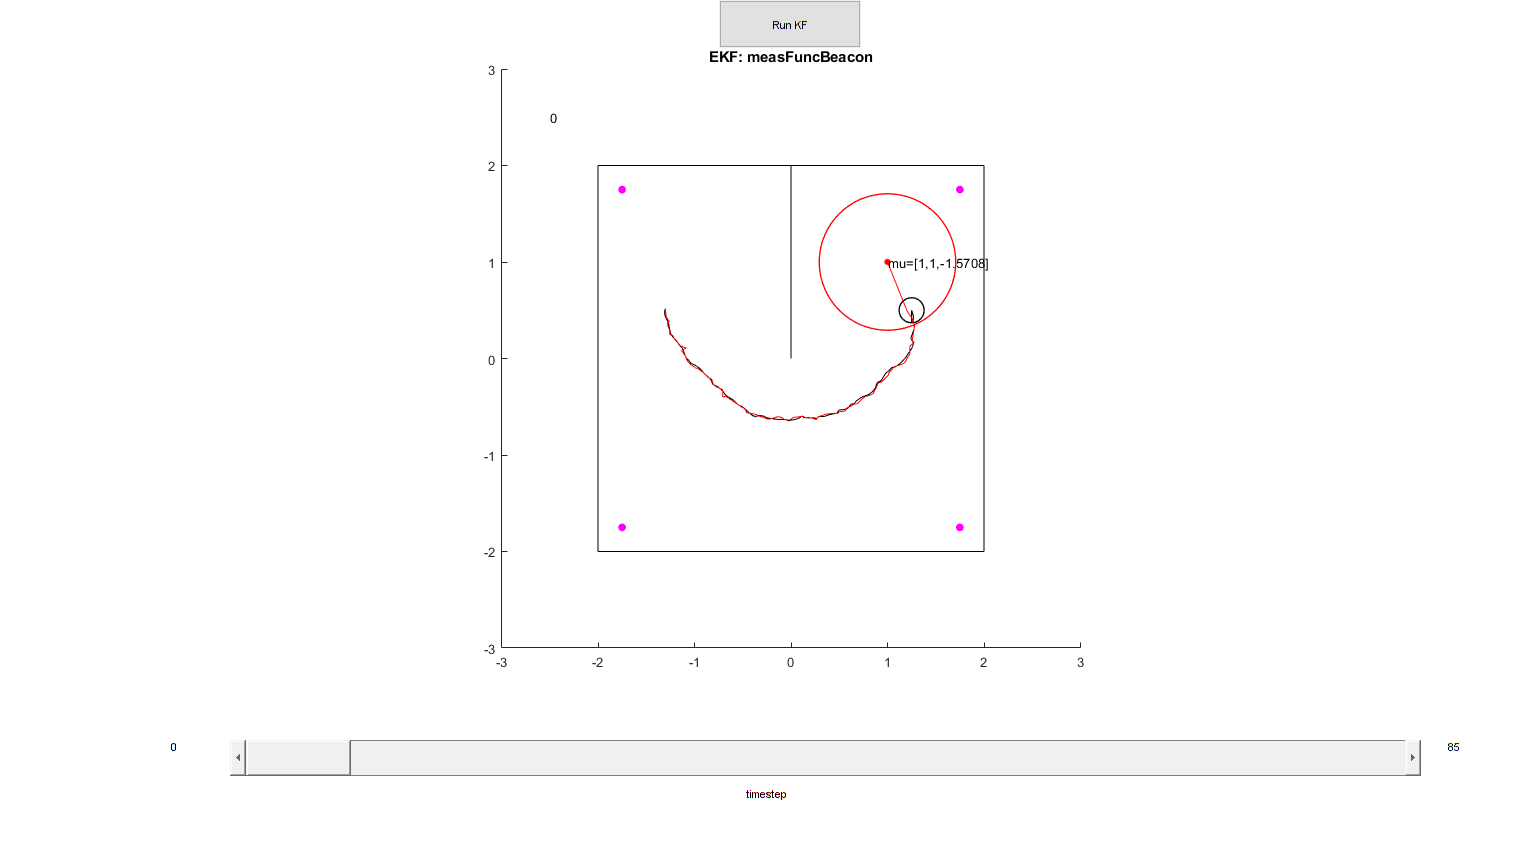

% The code creates a plot of the result.
plotKF(mu_hist,sigma_hist,robotXYtrajNoisy,ekfArgs.map,ekfArgs.measFunc, ekfArgs.beacons)

Now you can also calculate the error to gain more intution using different method and answer the above question

% calculate the error here
Error = norm(robotXYtrajNoisy - mu_hist)

Error = 0.6496

### Finished!

We can now localize the differential drive robot using LIDAR or beacons, each which have their own advantages and disadvantages. In the next exercise, we will introduce a different method of localization called the particle filter.